# Live Demo: Infectious disease spread in a neighborhood-level metapopulation model

### **6.336 Final Project**

**Suleeporn Yui Sujichantararat, Georgia Thomas, Jason Zhang     GROUP ID: DISEASE**

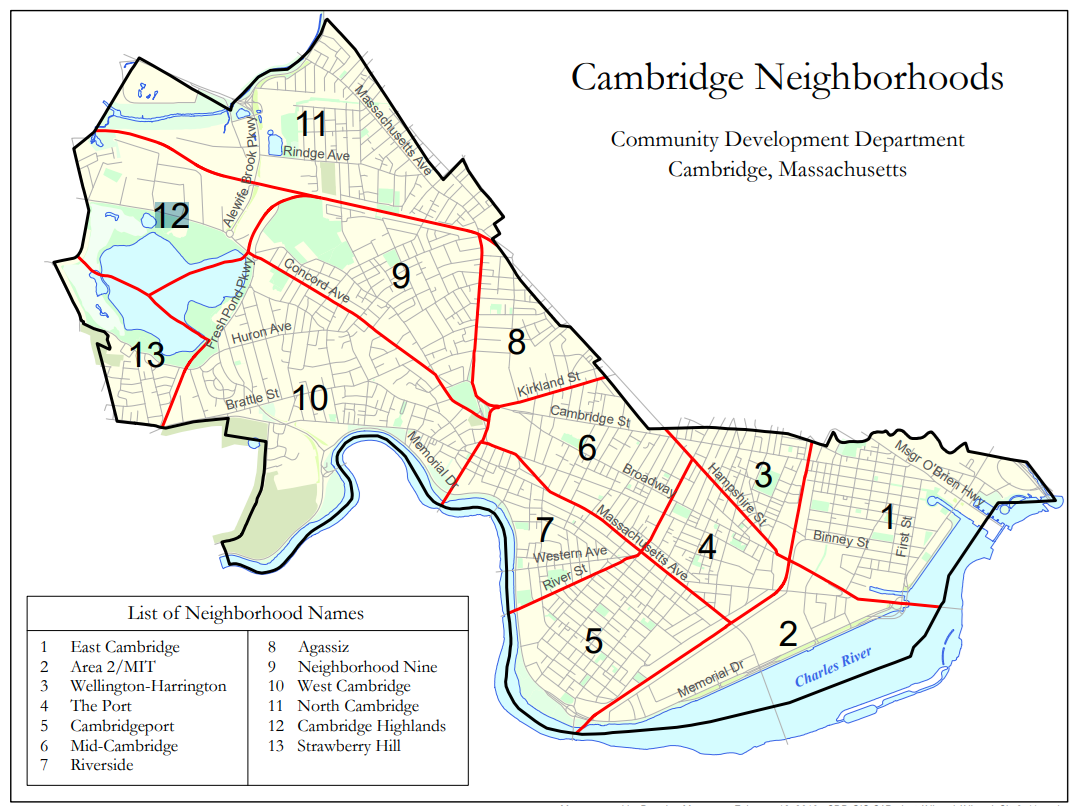

## **SEIR model, single neighborhood**

- One population with a single infected person, simulate from 0 to 100 days

- $\theta_{ij}$ = 0, no travel/commute from or to any other neighborhood

- $x_{sim,1}$ contains  $[S_1, E_1, I_1, R_1 ...S_P, E_P, I_P, R_P ]^T$ for all time

- $y_{sim,1}$ contains  $[\sum_{i=1}^{P} S_i,\;\;\sum_{i=1}^{P} E_i,\;\; \sum_{i=1}^{P} I_i,\;\;\sum_{i=1}^{P} R_i]^T$ for all time

% Simulation parameters
numNeighborhoods = 1;
cases = {'noTravel','noMeasures','cutOffMultiple'};
stateInitType = {'singleInfectedAll', 'MIToutbreak'};

% Simulation
[ySim1, xSim1] = SimSEIR(numNeighborhoods, cases{1}, stateInitType{1});

Timestep 1, Time 0.50, Newton Iter 1, nf 7.070737e+00, ndx 7.244007e+00
Timestep 1, Time 0.50, Newton Iter 2, nf 1.297536e-04, ndx 1.362655e-04
Timestep 1, Time 0.50, Newton Iter 3, nf 7.940314e-11, ndx 8.337495e-11
Timestep 2, Time 1.00, Newton Iter 1, nf 7.070737e+00, ndx 7.244007e+00
Timestep 2, Time 1.00, Newton Iter 2, nf 1.297536e-04, ndx 1.362655e-04
Timestep 2, Time 1.00, Newton Iter 3, nf 7.940314e-11, ndx 8.337495e-11
Timestep 3, Time 1.50, Newton Iter 1, nf 7.420140e+00, ndx 8.508936e+00
Timestep 3, Time 1.50, Newton Iter 2, nf 7.020285e-04, ndx 7.371692e-04
Timestep 3, Time 1.50, Newton Iter 3, nf 4.278648e-10, ndx 4.493137e-10
Timestep 4, Time 2.00, Newton Iter 1, nf 9.597846e+00, ndx 1.177639e+01
Timestep 4, Time 2.00, Newton Iter 2, nf 1.921163e-03, ndx 2.016882e-03
Timestep 4, Time 2.00, Newton Iter 3, nf 1.180158e-09, ndx 1.238935e-09
Timestep 5, Time 2.50, Newton Iter 1, nf 1.395141e+01, ndx 1.764615e+01
Timestep 5, Time 2.50, Newton Iter 2, nf 4.895393e-03, ndx 5.137

Show the proportions of individuals in SEIR vs. time. Note that $y_{sim,1} = x_{sim,1}$ for the single neighborhood case.

Animate the SEIR trajectories.

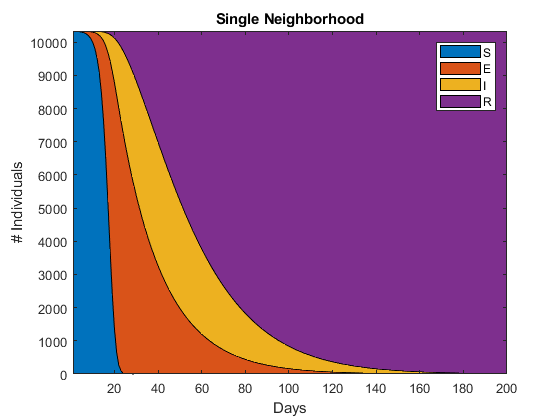

plotSEIRProp(ySim1,xSim1);

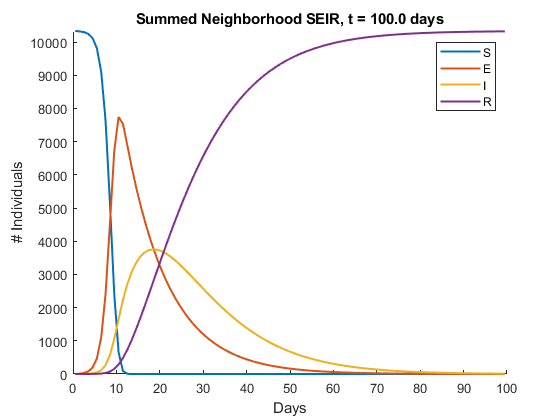

animationSpeed = 3;
animateSEIR(ySim1,animationSpeed);

##  SEIR metapopulation (multiple neighborhoods) model, with travel

- 13 neighborhoods, single infected person in Neighborhood 2 (MIT)

- $\theta_{ij} \ne 0$, unrestricted travel/commute between neighborhoods

- Corresponds to little public health intervention

% Simulation parameters
numNeighborhoods = 13;

% Simulation
[ySim2, xSim2] = SimSEIR(numNeighborhoods, cases{2}, stateInitType{2});

Timestep 1, Time 0.50, Newton Iter 1, nf 1.345279e+01, ndx 6.054172e+00
Timestep 1, Time 0.50, Newton Iter 2, nf 3.358523e-03, ndx 2.362449e-03
Timestep 1, Time 0.50, Newton Iter 3, nf 2.284803e-08, ndx 1.607911e-08
Timestep 2, Time 1.00, Newton Iter 1, nf 1.345279e+01, ndx 6.054172e+00
Timestep 2, Time 1.00, Newton Iter 2, nf 3.358523e-03, ndx 2.362449e-03
Timestep 2, Time 1.00, Newton Iter 3, nf 2.284803e-08, ndx 1.607911e-08
Timestep 3, Time 1.50, Newton Iter 1, nf 3.459095e+00, ndx 3.069000e+00
Timestep 3, Time 1.50, Newton Iter 2, nf 1.558938e-04, ndx 1.110722e-04
Timestep 3, Time 1.50, Newton Iter 3, nf 1.121428e-09, ndx 7.537957e-10
Timestep 4, Time 2.00, Newton Iter 1, nf 2.702305e+00, ndx 2.552173e+00
Timestep 4, Time 2.00, Newton Iter 2, nf 3.424997e-05, ndx 2.905430e-05
Timestep 4, Time 2.00, Newton Iter 3, nf 1.774141e-10, ndx 1.163324e-10
Timestep 5, Time 2.50, Newton Iter 1, nf 2.457028e+00, ndx 2.599139e+00
Timestep 5, Time 2.50, Newton Iter 2, nf 3.398619e-05, ndx 2.804

Show the proportions of individuals in SEIR vs. time.

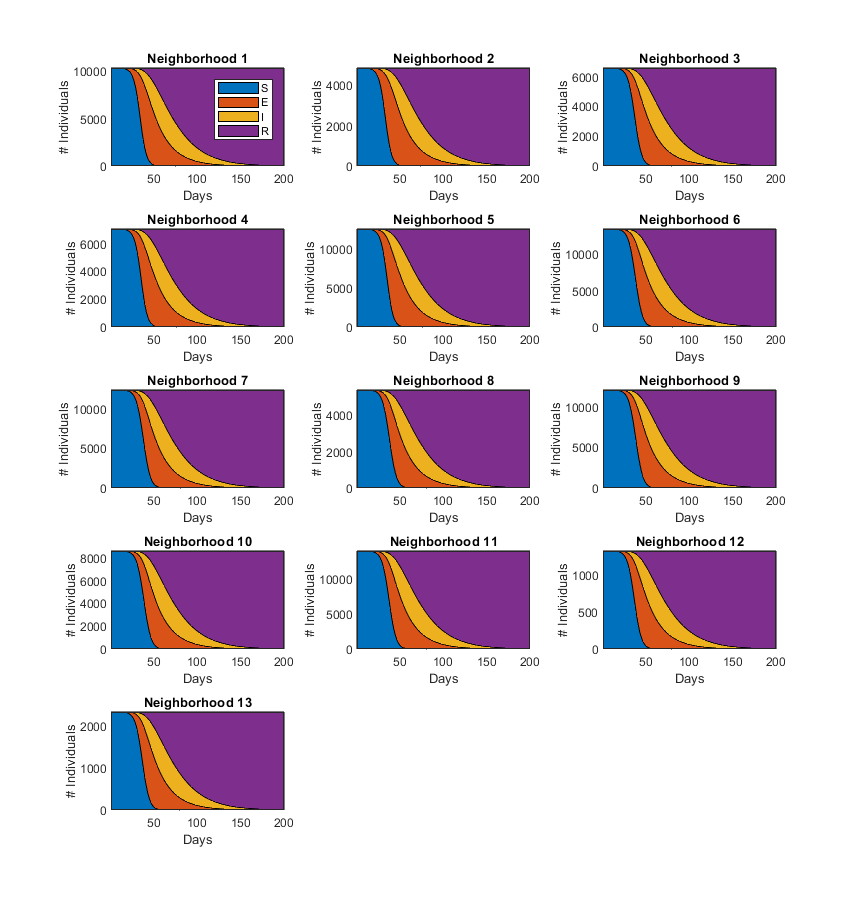

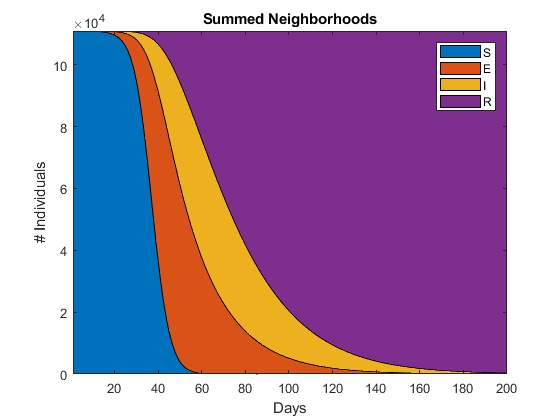

close all;
plotSEIRProp(ySim2,xSim2);

Animate the SEIR trajectories.

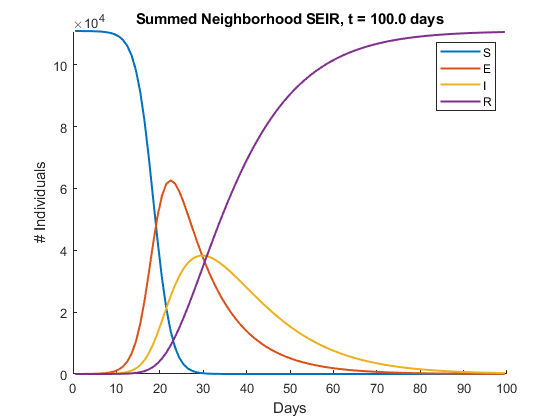

animationSpeed = 3;
animateSEIR(ySim2,animationSpeed);

Visualize  geographic spread.

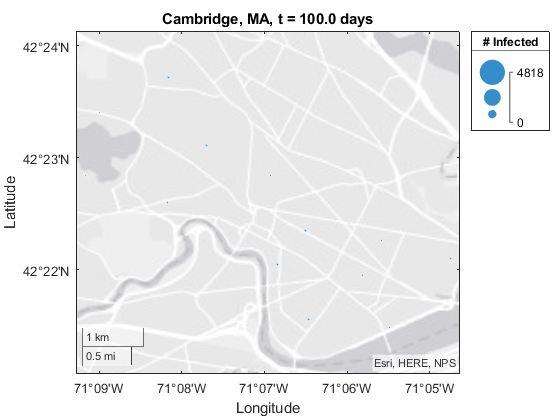

geovisSEIR(xSim2);

##  SEIR metapopulation model, with travel and neighborhood quarantine

- 12 neighborhoods, single infected person in Neighborhood 2

- $\theta_{ij} \ne 0$ except for neighborhoods 1,2 and 5, which are isolated (no travel/commute from or to any other neighborhood)

- Equivalent to zeroing out the 1st, 2nd, and 5th rows & columns in $\theta_{ij}$

- We hope to see a flattened curve for I.

% Simulation parameters
numNeighborhoods = 13;

% Simulation
[ySim3, xSim3] = SimSEIR(numNeighborhoods, cases{3}, stateInitType{2});

Timestep 1, Time 0.50, Newton Iter 1, nf 7.044075e+00, ndx 6.942209e+00
Timestep 1, Time 0.50, Newton Iter 2, nf 1.193117e-04, ndx 1.227583e-04
Timestep 1, Time 0.50, Newton Iter 3, nf 1.031714e-10, ndx 1.035257e-10
Timestep 2, Time 1.00, Newton Iter 1, nf 7.044075e+00, ndx 6.942209e+00
Timestep 2, Time 1.00, Newton Iter 2, nf 1.193117e-04, ndx 1.227583e-04
Timestep 2, Time 1.00, Newton Iter 3, nf 1.031714e-10, ndx 1.035257e-10
Timestep 3, Time 1.50, Newton Iter 1, nf 6.843648e+00, ndx 7.571191e+00
Timestep 3, Time 1.50, Newton Iter 2, nf 1.069958e-03, ndx 1.100704e-03
Timestep 3, Time 1.50, Newton Iter 3, nf 9.303759e-10, ndx 9.332712e-10
Timestep 4, Time 2.00, Newton Iter 1, nf 8.298439e+00, ndx 9.878962e+00
Timestep 4, Time 2.00, Newton Iter 2, nf 2.779940e-03, ndx 2.858541e-03
Timestep 4, Time 2.00, Newton Iter 3, nf 2.433632e-09, ndx 2.440896e-09
Timestep 5, Time 2.50, Newton Iter 1, nf 1.145439e+01, ndx 1.410498e+01
Timestep 5, Time 2.50, Newton Iter 2, nf 6.570438e-03, ndx 6.751

Show the proportions of individuals in SEIR vs. time.

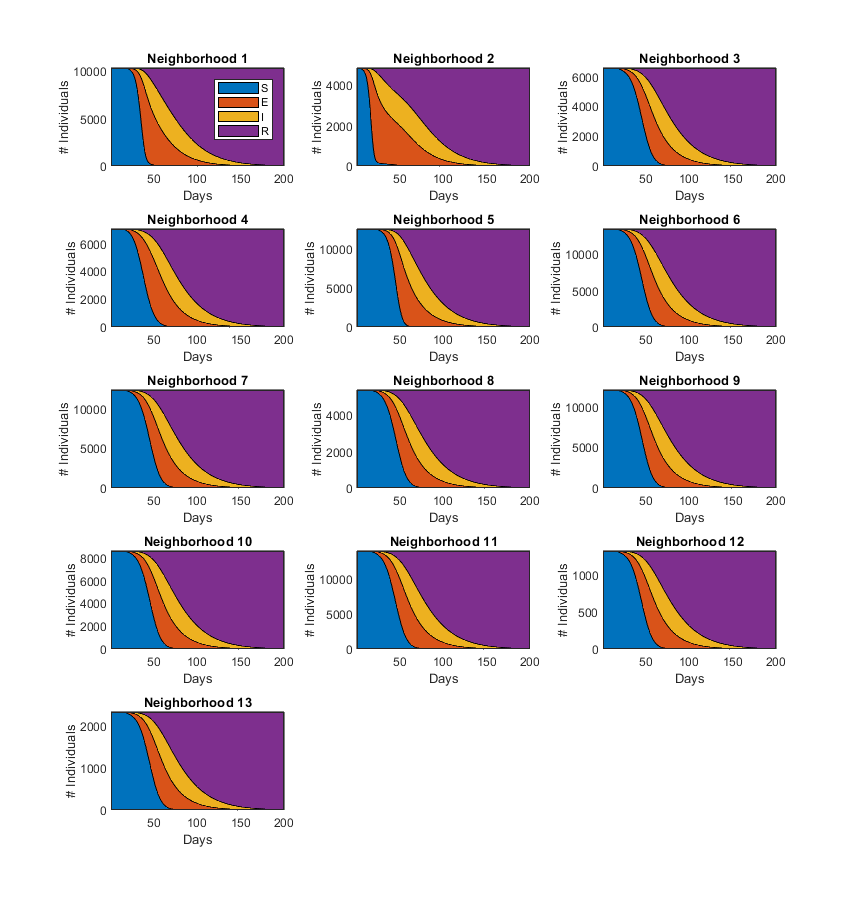

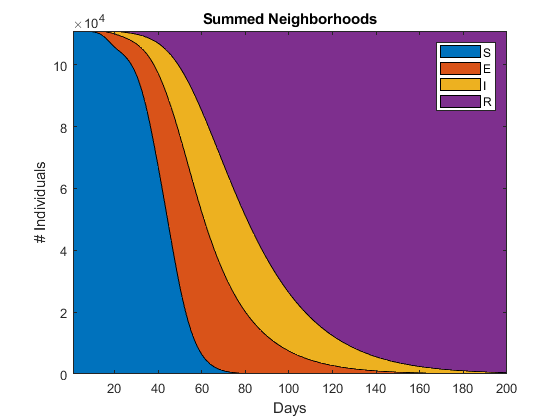

close all;
plotSEIRProp(ySim3,xSim3);

Animate the SEIR trajectories.

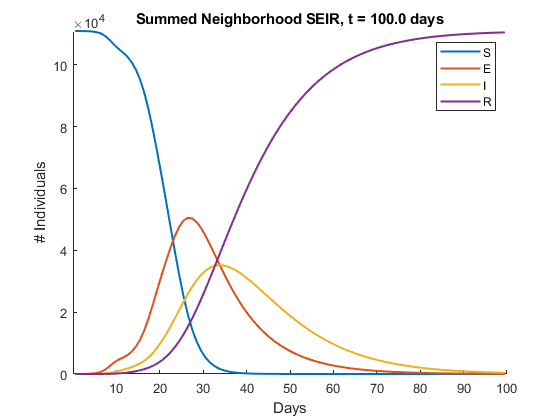

animationSpeed = 3;
animateSEIR(ySim3,animationSpeed);

Visualize  geographic spread.

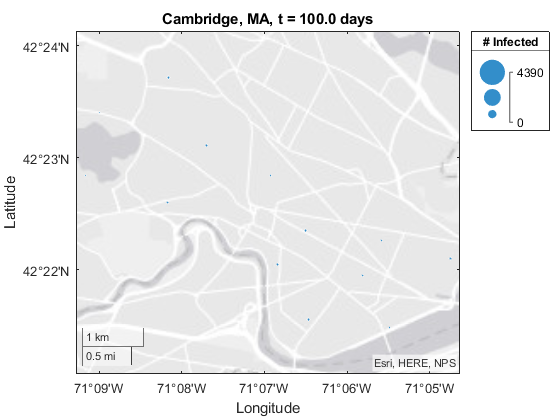

geovisSEIR(xSim3);